# 动态趋势线可视化

- [Zhihu: https://www.zhihu.com/people/1105936347](https://www.zhihu.com/people/1105936347)

- [Github: https://github.com/AFei19911012](https://github.com/AFei19911012)

数据来源于美国的新型冠状肺炎疫情实时数据报告：[https://voice.baidu.com/act/newpneumonia/newpneumonia/?from=osari_pc_1&city=%E7%BE%8E%E5%9B%BD-%E7%BE%8E%E5%9B%BD](https://voice.baidu.com/act/newpneumonia/newpneumonia/?from=osari_pc_1&city=%E7%BE%8E%E5%9B%BD-%E7%BE%8E%E5%9B%BD)

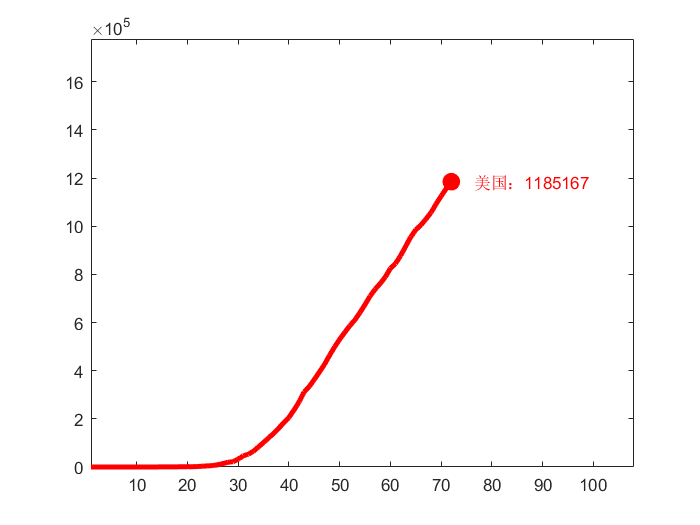

clear; clc; close;
% 数据，可以补充最好
y = [34,34,34,53,57,60,60,64,69,89,106,125,161,233,345,445,572,717,1010,1322,1264,1678,3489,...
     4629,5894,9345,14250,19624,22043,32717,46332,53268,65285,83507,101657,121117,139675,...
     161367,184183,206207,236339,270473,312076,334125,363349,394182,425828,463433,498674,...
     530384,559245,586941,610632,641397,674829,710021,738697,762496,789383,825306,844992,...
     877497,916348,955488,985060,1004942,1029878,1056646,1092656,1125305,1156744,1185167];
len = length(y);
x = 1:len;
% 第一个点为标记点
plot(x(1), y(1), 'or', 'MarkerSize', 10, 'MarkerFaceColor', 'r');
hold on
% 循环画图
for i = 2:len
    % 画两个点
    plot(x(i-1:i), y(i-1:i), 'r', 'LineWidth', 3);
    % 设置一下范围
    xlim([1, 1.5*x(i)]);
    ylim([0, 1.5*y(i)]);
    % 删掉之前的文本和标记
    delete(findobj('Type','text'));
    delete(findobj('Marker','o'));
    % 画标记点
    plot(x(i), y(i), 'or', 'MarkerSize', 10, 'MarkerFaceColor', 'r');
    % 添加标注
    text(x(i),y(i),['     美国：', num2str(y(i))], 'Color', 'r');    
    % 暂停 0.1s
    pause(0.1)
end
hold off